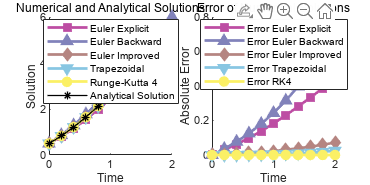

clc, clear, close all
odefun = @(x, y) y - x^2 + 1;  % 定义微分方程
a = 0;                         % 区间左端点
b = 2;                         % 区间右端点
y0 = 0.5;                      % 设置初始值
tspan = [a, b];
n = 10;
% 使用不同的求解器求解
[t, yEuler] = eulerExplicit(odefun, tspan, y0, n);
[t, yEulerBack] = eulerBackward(odefun, tspan, y0, n);
[t, yEulerImproved] = eulerImproved(odefun, tspan, y0, n);
[t, yTrapezoidal] = eulerTrapezoidal(odefun, tspan, y0, n);
[t, yRK4] = rungeKutta4(odefun, tspan, y0, n);
% 计算解析解
y_real_fun = @(t) 2 * t - exp(t) / 2 + t.^2 + 1;
y_real = y_real_fun(t);
colors = [
189 77 163
129 130 186
181 133 129
136 198 226
251 240 101
197 228 231
] / 255;  % 将颜色值归一化到 [0, 1] 范围

% 创建一个新图形窗口
figure('Position', [100, 100, 1000, 500])

% 画出所有求解器的解以及解析解
subplot(1, 2, 1)
hold on
plot(t, yEuler, '-s', 'Color', colors(1,:), 'LineWidth', 2, 'MarkerFaceColor', colors(1,:), 'DisplayName', 'Euler Explicit')
plot(t, yEulerBack, '-^', 'Color', colors(2,:), 'LineWidth', 2, 'MarkerFaceColor', colors(2,:), 'DisplayName', 'Euler Backward')
plot(t, yEulerImproved, '-d', 'Color', colors(3,:), 'LineWidth', 2, 'MarkerFaceColor', colors(3,:), 'DisplayName', 'Euler Improved')
plot(t, yTrapezoidal, '-v', 'Color', colors(4,:), 'LineWidth', 2, 'MarkerFaceColor', colors(4,:), 'DisplayName', 'Trapezoidal')
plot(t, yRK4, '-o', 'Color', colors(5,:), 'LineWidth', 2, 'MarkerFaceColor', colors(5,:), 'DisplayName', 'Runge-Kutta 4')
plot(t, y_real, '-*', 'Color', [0, 0, 0], 'LineWidth', 1, 'MarkerFaceColor', [0 0 0], 'DisplayName', 'Analytical Solution')
legend('show', 'Location', 'best')
title('Numerical and Analytical Solutions')
xlabel('Time')
ylabel('Solution')
hold off

% 计算并绘制各方法的误差
subplot(1, 2, 2)
hold on
plot(t, abs(yEuler - y_real), '-s', 'Color', colors(1,:), 'LineWidth', 2, 'MarkerFaceColor', colors(1,:), 'DisplayName', 'Error Euler Explicit')
plot(t, abs(yEulerBack - y_real), '-^', 'Color', colors(2,:), 'LineWidth', 2, 'MarkerFaceColor', colors(2,:), 'DisplayName', 'Error Euler Backward')
plot(t, abs(yEulerImproved - y_real), '-d', 'Color', colors(3,:), 'LineWidth', 2, 'MarkerFaceColor', colors(3,:), 'DisplayName', 'Error Euler Improved')
plot(t, abs(yTrapezoidal - y_real), '-v', 'Color', colors(4,:), 'LineWidth', 2, 'MarkerFaceColor', colors(4,:), 'DisplayName', 'Error Trapezoidal')
plot(t, abs(yRK4 - y_real), '-o', 'Color', colors(5,:), 'LineWidth', 2, 'MarkerFaceColor', colors(5,:), 'DisplayName', 'Error RK4')
legend('show', 'Location', 'best')
title('Error of Numerical Solutions')
xlabel('Time')
ylabel('Absolute Error')
hold off